# PART 3: Control

## Exercise 3.1

Using the non-linear model of Exercise 2.1 (or 2.2), close a feedback control loop to control the attitude, to allow setting roll, pitch, yaw and altitude references. Choose the gains of the PID by tuning on the linearized system, by minimizing the settling time while ensuring that the controlled system is critically damped (no overshoot), and plot the step response for a step of:

- 
$$\Theta ^* = [10, 0, 0]^T \ [deg], \ z^* = 0[m]$$


- 
$$\Theta ^* = [0, 10, 0]^T \ [deg], \ z^* = 0[m]$$


- 
$$\Theta ^* = [0, 0, 10]^T \ [deg], \ z^* = 0[m]$$


- 
$$\Theta ^* = [0, 0, 0]^T \ [deg], \ z^* = 1[m]$$


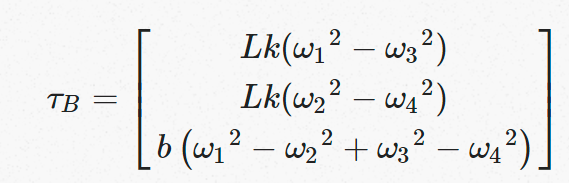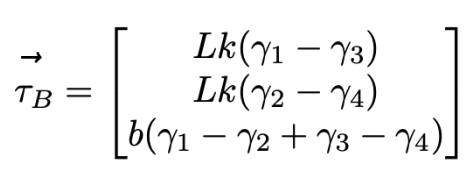

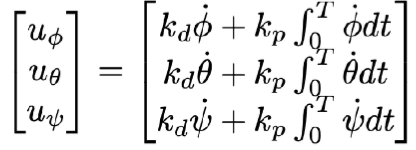

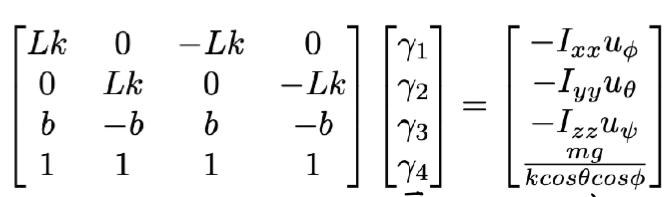

syms L k b I_xx I_yy I_zz u_phi u_theta u_psi m g theta phi psi
syms theta_dot phi_dot psi_dot f_cz
Att = [ L*k 0 -L*k 0;
        0 L*k 0 -L*k;
        b -b b -b;
        1 1 1 1]

$$Att = \left(\begin{array}{cccc} L\,k & 0 & -L\,k & 0\\ 0 & L\,k & 0 & -L\,k\\ b & -b & b & -b\\ 1 & 1 & 1 & 1 \end{array}\right)$$

pinv(Att)

$$ans = \left(\begin{array}{cccc} \frac{1}{2\,L\,k} & 0 & \frac{1}{4\,b} & \frac{1}{4}\\ 0 & \frac{1}{2\,L\,k} & -\frac{1}{4\,b} & \frac{1}{4}\\ -\frac{1}{2\,L\,k} & 0 & \frac{1}{4\,b} & \frac{1}{4}\\ 0 & -\frac{1}{2\,L\,k} & -\frac{1}{4\,b} & \frac{1}{4} \end{array}\right)$$

% thrust force 
T_B = [ -I_xx * u_phi;
      -I_yy * u_theta;
      -I_zz * u_psi;
      (m*g+f_cz)/(k*cos(theta)*cos(phi))]

$$T\_B = \left(\begin{array}{c} -I_{\mathrm{xx}}\,u_{\varphi }\\ -I_{\mathrm{yy}}\,u_{\theta }\\ -I_{\mathrm{zz}}\,u_{\psi }\\ \frac{f_{\mathrm{cz}}+g\,m}{k\,\cos\left(\varphi \right)\,\cos\left(\theta \right)} \end{array}\right)$$

gamma = pinv(Att) * T_B

$$gamma = \begin{array}{l} \left(\begin{array}{c} \sigma_{1}-\frac{I_{\mathrm{zz}}\,u_{\psi }}{4\,b}-\frac{I_{\mathrm{xx}}\,u_{\varphi }}{2\,L\,k}\\ \frac{I_{\mathrm{zz}}\,u_{\psi }}{4\,b}+\sigma_{1}-\frac{I_{\mathrm{yy}}\,u_{\theta }}{2\,L\,k}\\ \sigma_{1}-\frac{I_{\mathrm{zz}}\,u_{\psi }}{4\,b}+\frac{I_{\mathrm{xx}}\,u_{\varphi }}{2\,L\,k}\\ \frac{I_{\mathrm{zz}}\,u_{\psi }}{4\,b}+\sigma_{1}+\frac{I_{\mathrm{yy}}\,u_{\theta }}{2\,L\,k} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{f_{\mathrm{cz}}+g\,m}{4\,k\,\cos\left(\varphi \right)\,\cos\left(\theta \right)} \end{array}$$

### Load data from previous

load('Exercise_2_Workspace.mat')

## Linearlizet the nonlinear model

input: RPM $\omega
$

outpu: position and euler rate$\left[\matrix{x \cr y \cr z \cr \dot{\phi} \cr \dot{\theta} \cr \dot{\psi}}\right]$

TakeStep = 0;
[AA,BB,CC,DD] = linmod('MyEx_3_Nonlinear',x0,uss);

sys = ss(AA,BB,CC,DD)

sys =
 
  A = 
           x1     x2     x3     x4     x5     x6     x7     x8     x9    x10    x11    x12
   x1       0      0      0      1      0      0      0      0      0      0      0      0
   x2       0      0      0      0      1      0      0      0      0      0      0      0
   x3       0      0      0      0      0      1      0      0      0      0      0      0
   x4       0      0      0  -0.01      0      0      0   9.81      0      0      0      0
   x5       0      0      0      0  -0.01      0  -9.81      0      0      0      0      0
   x6       0      0      0      0      0  -0.01      0      0      0      0      0      0
   x7       0      0      0      0      0      0      0      0      0      1      0      0
   x8       0      0      0      0      0      0      0      0      0      0      1      0
   x9       0      0      0      0      0      0      0      0      0      0      0      1
   x10      0      0      0      0      0      0      0      0      0      

## Exercise 3.1  Close a feedback control loop to control the attitude

- 
$$ \Theta^*= [10, 0, 0]^T \  
[deg], \  
z^*= 0[m]
$$


- 
$$ \Theta^*= [0, 10, 0]^T \  
[deg], \  
z^*= 0[m]
$$


- 
$$ \Theta^*= [10, 0, 0]^T \  
[deg], \  
z^*= 0[m]
$$


- 
$$ \Theta^*= [10, 0, 0]^T \  
[deg], \  
z^*= 0[m]
$$
